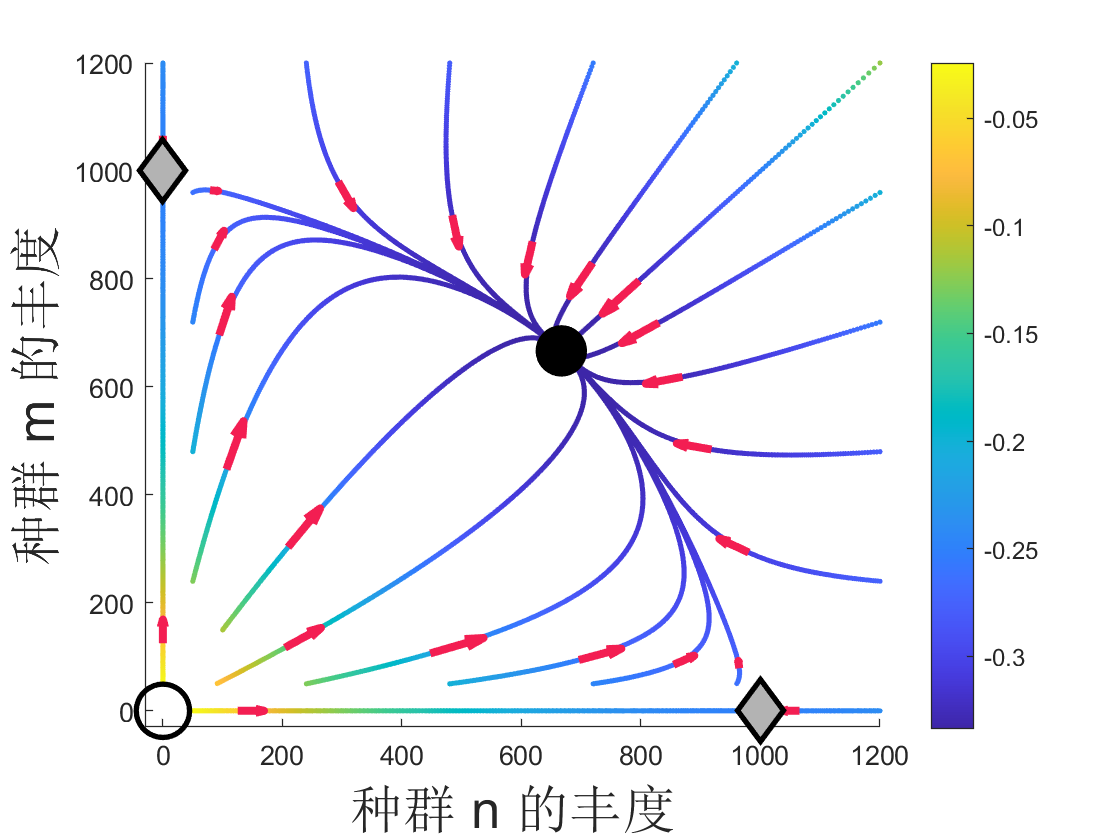

way = 'D:/Code/C/level2/work3/fig1_rk4.bin';
clc;



fileID1=fopen(way,'r');
A = fread(fileID1,[4 inf],'double');
fclose(fileID1);
N = 9950;

figure;
hold on


for i=0:22
    paint(A,1+N*i,N*i+N)
    i;
end
scatter(1000,0,300,"d", ...
    'MarkerEdgeColor',"black",'MarkerFaceColor',[.7,.7,.7],"LineWidth",2)
scatter(0,1000,300,"d", ...
    'MarkerEdgeColor',"black",'MarkerFaceColor',[.7,.7,.7],"LineWidth",2)
scatter(666.7,666.7,300,"o", ...
    'MarkerEdgeColor',"black",'MarkerFaceColor',"black","LineWidth",2)
scatter(0,0,400,"o", ...
    'MarkerEdgeColor',"black","LineWidth",2)

xlim([-30 1200])
ylim([-30 1200])
hold off

xlabel('种群 n 的丰度',"FontSize",20)
ylabel('种群 m 的丰度',"FontSize",20)
colorbar

function paint(A,x1,x2)
scatter(A(2,x1:x2),A(3,x1:x2),4,(A(4,x1:x2)),'filled')
dist = sqrt((A(2,x1:x2)-666.7).^2 + (A(3,x1:x2)-666.7).^2);
s.AlphaData = dist;
s.MarkerFaceAlpha = 'flat';
quiver(A(2,100+x1),A(3,100+x1),A(2,100+x1+2)-A(2,100+x1),A(3,100+x1+2)-A(3,100+x1),"MaxHeadSize",100,"MarkerSize",100,"LineWidth",3,"AutoScaleFactor",20,"Color",[0.6350 0.0780 0.2140]*1.5)
end
